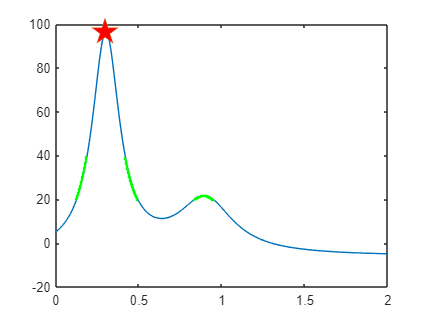

x = linspace(0, 2, 1000);
y = humps(x);
[~, idx] = max(y);
plot(x, humps(x))
hold on
plot(x(idx), y(idx), '-p', "MarkerSize", 20, "MarkerFaceColor", "red")
plot(x(find(y >= 20 & y <= 40)), y(find(y >= 20 & y <= 40)), 'g.')
hold off

n = 13.7

n = 13.7000

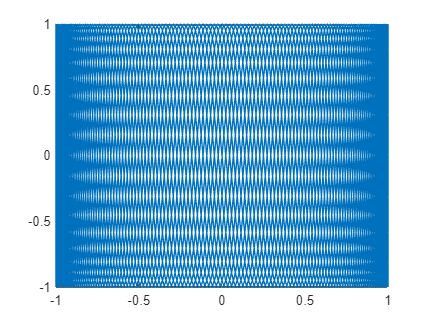

task_10(1, 1, 0:.01:20*pi, 0, 1, n)

task_11(t, 1/4, 1/16, 8, 8)

t = linspace(-5, 5, 1000);
max_s = 5;
for j = 1:1000
    for i = 1:max_s
        temp = 1;
        if mod(i, 2) == 1
            temp = -1;
        end
        [x0, y0] = task_12(t, i, 1/4, 1/16, 8, 8, (i/4)*j/2 *temp);
        plot(x0, y0)
        hold on
    end
    pause(0.100);
    hold off
end


function task_10(a, b, phi, phi_0, n, m)
    x = a*sin(n*phi + phi_0);
    y = b*sin(m*phi);
    plot(x, y)
end

function task_11(t, a, b, m, n)
    x = cos(t) + a*cos(m*t) + b*sin(n*t);
    y = sin(t) + a*sin(m*t) + b*cos(n*t);
    plot(x, y)
end

function [x, y] = task_12(t, k, a, b, m, n, phi)
    x = cos(t) - a*cos(m*t + phi) + b*sin(n*t + phi);
    y = sin(t) + a*sin(m*t + phi) + b*cos(n*t + phi);
    x = x/k;
    y = y/k;
end